% Тевт спестр

NAvg = 100;
Fs = 1e6;
FrameSize = 64;
NumFreqBins = 512;
filterBankRBW = Fs/NumFreqBins;

sinegen = dsp.SineWave('SampleRate',Fs,'SamplesPerFrame',FrameSize);

filterBankSA = dsp.SpectrumAnalyzer(...
    'Method','Filter bank',...
    'NumTapsPerBand',24,...
    'SampleRate',Fs,...
    'RBWSource','Property',...
    'RBW',filterBankRBW,...
    'SpectralAverages',NAvg,...
    'PlotAsTwoSidedSpectrum',false,...
    'YLimits',[-150 50],...
    'YLabel','Power',...
    'Title','Filter bank Power Spectrum Estimate',...
    'Position',[50 375 800 450]);

release(sinegen)
sinegen.Amplitude = [1 2];
sinegen.Frequency = [200000 250000];

noiseVar = 1e-12;
noiseFloor = 10*log10((noiseVar/(NumFreqBins/2))/1e-3); % -114 dBm onesided
fprintf('Noise Floor\n');

Noise Floor


fprintf('Filter bank noise floor = %.2f dBm\n\n',noiseFloor);

Filter bank noise floor = -114.08 dBm



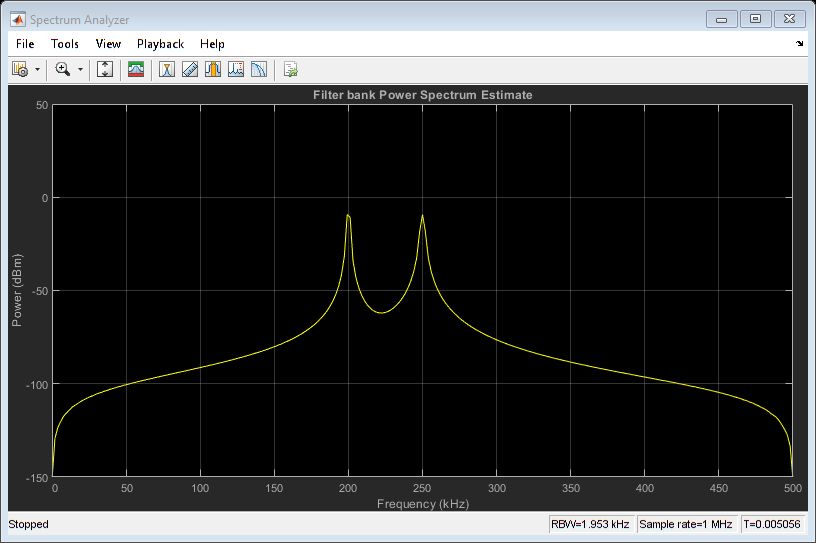


timesteps = 10 * ceil(NumFreqBins / FrameSize);
for t = 1:timesteps
    x = sum(sinegen(),2) + sqrt(noiseVar)*randn(FrameSize,1);
    filterBankSA(x);
end

release(filterBankSA)